# Experiment 5.1

## Name: Tim Roche

## Objectives

To verify the equivalency of the basic forms, including cascade, parallel, and feedback forms. To verify the equivalency of the basic moves, including moving blocks past summing junctions, and moving blocks past pickoff points.  

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

*Find the equivalent transfer function of three cascaded blocks, *$G_1(s) = \frac{1}{s+1}$*, *$G_2(s) = \frac{1}{s+4}$*, and *$G_3(s) = \frac{s+1}{s+5}$*.*

**Answer:**

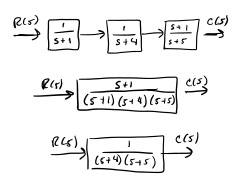

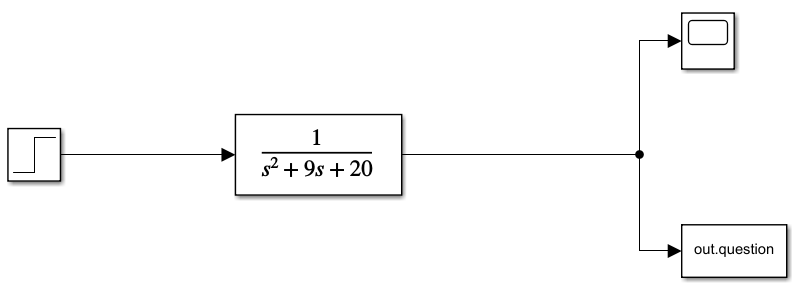

### Problem 2

*Find the equivalent transfer function of three parallel blocks, *$G_1(s) = \frac{1}{s+4}$*, *$G_2(s) = \frac{1}{s+4}$*, and *$G_3(s) = \frac{s+3}{s+5}$*.*

**Answer:**

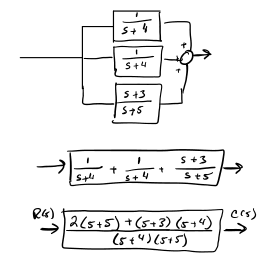

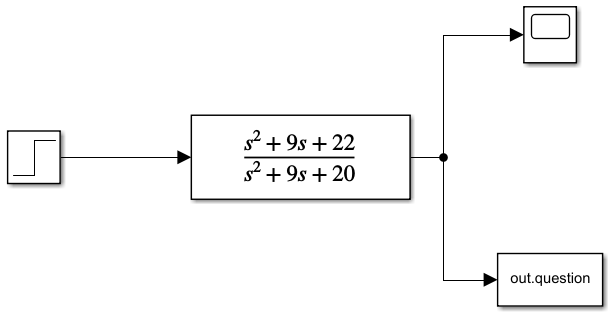

### Problem 3

*Find the equivalent transfer funciton of the negative feedback system of Figure P5.55 (picture below) if *$G(s) = \frac{s+1}{s(s+2)}$*, and *$H(s)=\frac{s+3}{s+4}$*.*

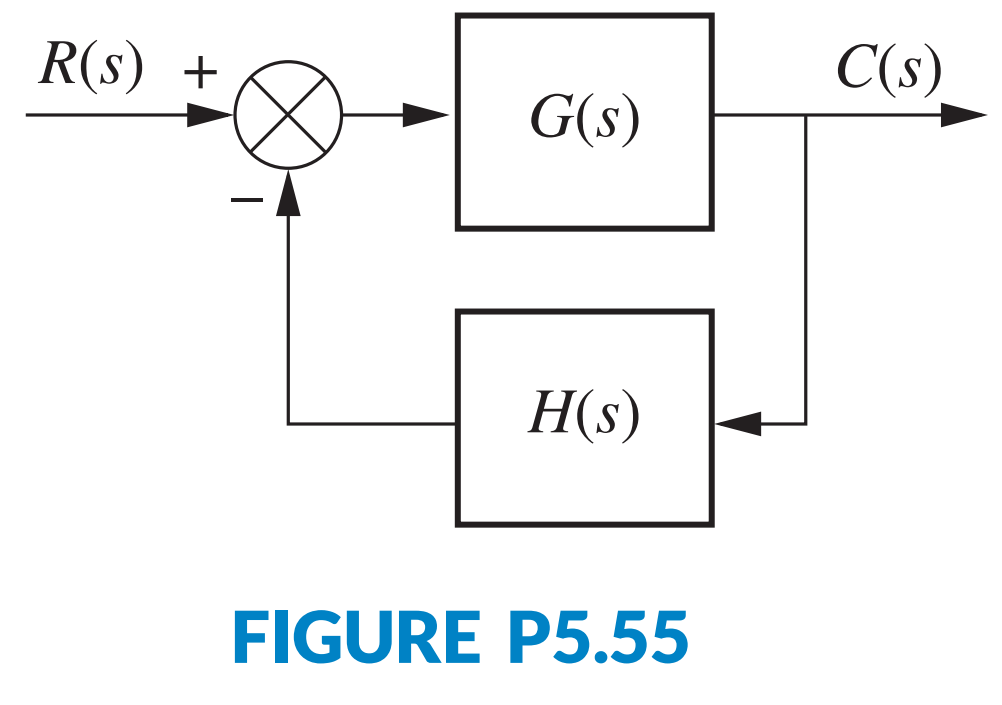

**Answer:**

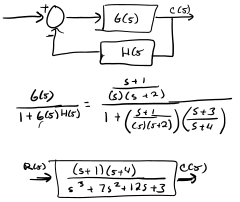

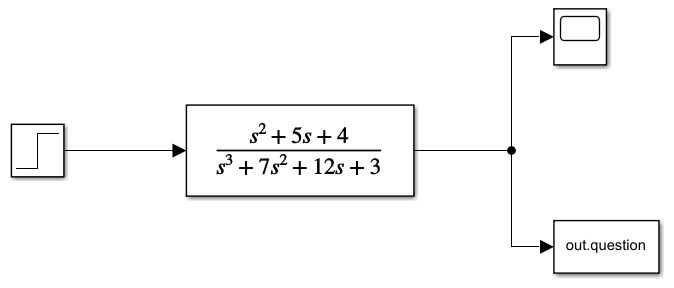

### Problem 4

*For the system of **Prelab 3**, push *$H(s)$* to the left past the summing junction and draw the equivalent system.*

**Answer:**

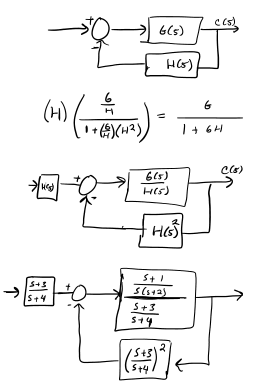

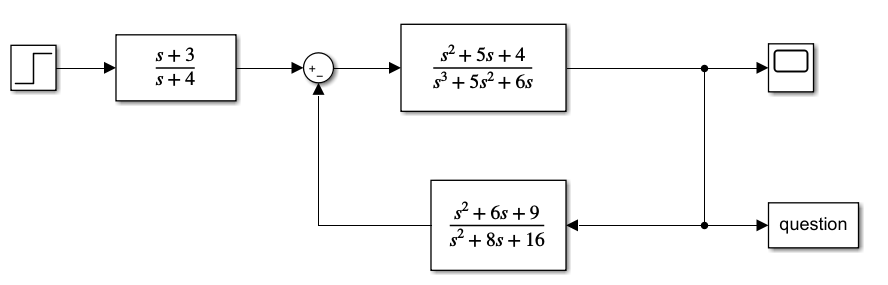

### Problem 5

*For the system of **Prelab 3**, push *$H(s)$* to the right past the pickoff point and draw the equivalent system. *

**Answer:**

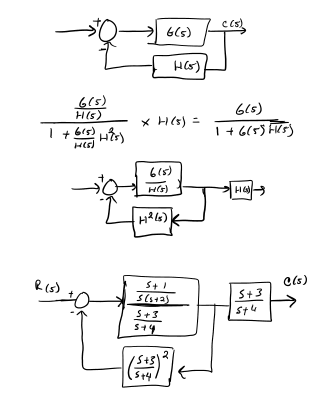

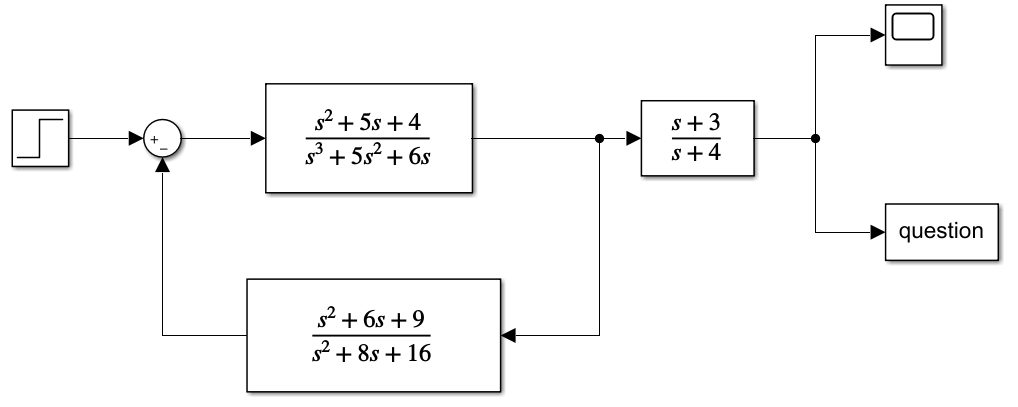

## Lab

### Problem 1

*Using Simulink, set up the cascade system of **Prelab 1** and the equivalent single block. Make separate plots of the step response of the cascaded system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

***Original ***

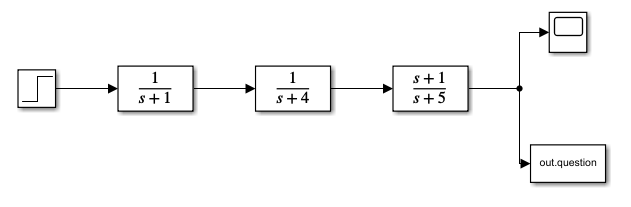

***Simplified***

fc = 0;

%Original
fc=fc+1; figure(fc);
subplot(2,1,1);
simOut = sim('Part1og.slx','ReturnWorkspaceOutputs','on');
disp("Original")

Original


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.7728
    SettlingTime: 1.3379
     SettlingMin: 0.0469
     SettlingMax: 0.0500
       Overshoot: 6.6613e-14
      Undershoot: 0
            Peak: 0.0500
        PeakTime: 9.4111


plot(simOut.question.Time, simOut.question.Data)
title("Original Function")

%Simplified
subplot(2,1,2)
simOut = sim('Part1simp.slx','ReturnWorkspaceOutputs','on');
disp("Simplified")

Simplified


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.7683
    SettlingTime: 1.3233
     SettlingMin: 0.0456
     SettlingMax: 0.0500
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0500
        PeakTime: 9.7124


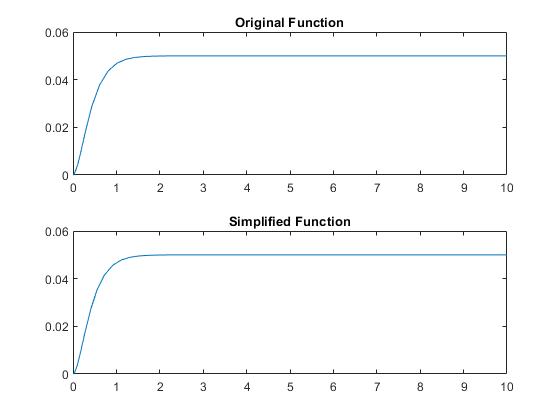

plot(simOut.question.Time, simOut.question.Data)
title("Simplified Function")

### Problem 2

*Using Simulink, set up the parallel system of **Prelab 2** and the equivalent single block. Make separate plots of the step response of the parallel system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

***Original***

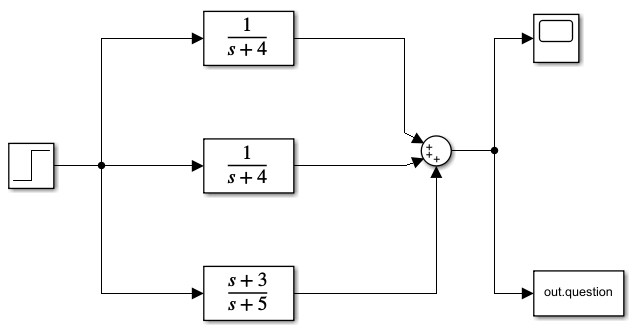

***Simplified***

%Original
fc=fc+1; figure(fc);
subplot(2,1,1);
simOut = sim('Part2og.slx','ReturnWorkspaceOutputs','on');
disp("Original")

Original


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.7699
    SettlingTime: 1.3359
     SettlingMin: 1.0948
     SettlingMax: 1.1000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.1000
        PeakTime: 9.0618


plot(simOut.question.Time, simOut.question.Data)
title("Original Function")

%Simplified
subplot(2,1,2)
simOut = sim('Part2simp.slx','ReturnWorkspaceOutputs','on');
disp("Simplified")

Simplified


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.7683
    SettlingTime: 1.3233
     SettlingMin: 1.0912
     SettlingMax: 1.1000
       Overshoot: 0
      Undershoot: 0
            Peak: 1.1000
        PeakTime: 9.3124


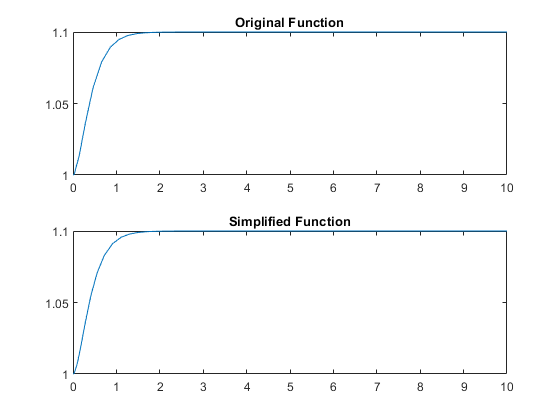

plot(simOut.question.Time, simOut.question.Data)
title("Simplified Function")

### Problem 3

*Using Simulink, set up the negative feedback system of **Prelab 3** and the equivalent single block. Make separate plots of the step response of the negative feedback system and its equivalent single block. Record the values of settling time and rise time for each step response.  *

***Original***

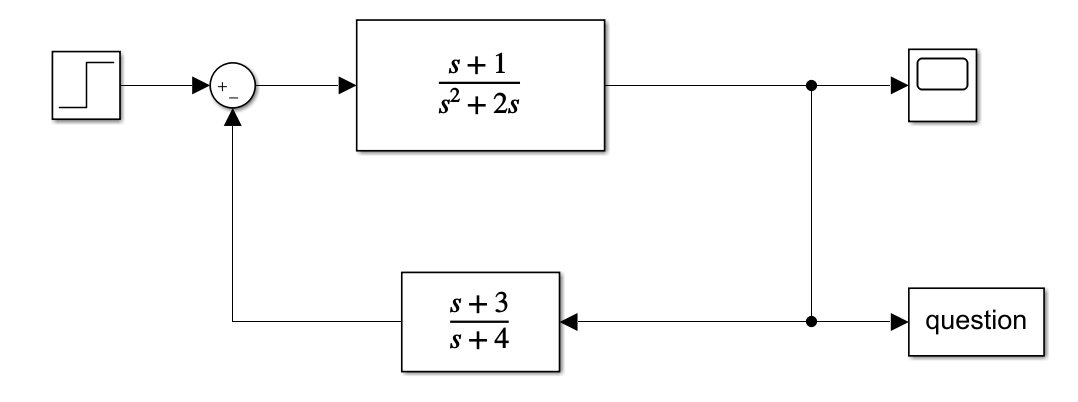

**Simplified**

%Original
fc=fc+1; figure(fc);
subplot(2,1,1);
simOut = sim('Part3og.slx','ReturnWorkspaceOutputs','on');
disp("Original")

Original


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


plot(simOut.question.Time, simOut.question.Data)
title("Original Function")

%Simplified
subplot(2,1,2)
simOut = sim('Part3simp.slx','ReturnWorkspaceOutputs','on');
disp("Simplified")

Simplified


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7627
    SettlingTime: 8.6887
     SettlingMin: 1.1592
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


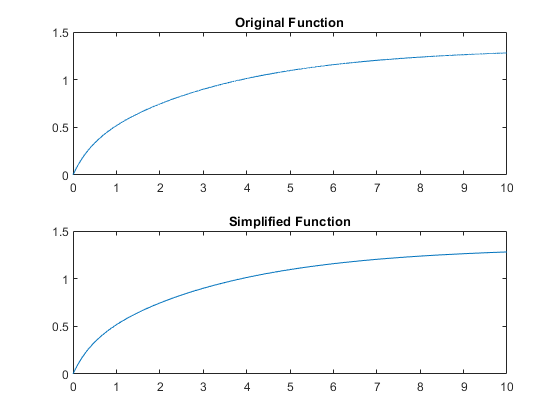

plot(simOut.question.Time, simOut.question.Data)
title("Simplified Function")

### Problem 4

*Using Simulink, set up the negative feeback systems of **Prelab 3**, **Prelab 4**, and **Prelab 5**. Make separate plots of the step response of each of the systems. Record the values of settling time and rise time for each step response.  *

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

*Prelab 3*

Prelab 4

Prelab 5

%Prelab 3
fc=fc+1; figure(fc);
subplot(3,1,1);
simOut = sim('Part3og.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 3")

Prelab 3


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


plot(simOut.question.Time, simOut.question.Data)
title("Original Function (Prelab 3)")

%Prelab 4
subplot(3,1,2)
simOut = sim('Part44Out.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 4")

Prelab 4


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


plot(simOut.question.Time, simOut.question.Data)
title("h(s) Pulled Left (Prelab 4)")

%Prelab 5
subplot(3,1,3)
simOut = sim('Part45Out.slx','ReturnWorkspaceOutputs','on');
disp("Prelab 5")

Prelab 5


stepinfo(simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 5.7635
    SettlingTime: 8.6876
     SettlingMin: 1.1523
     SettlingMax: 1.2803
       Overshoot: 0
      Undershoot: 0
            Peak: 1.2803
        PeakTime: 10


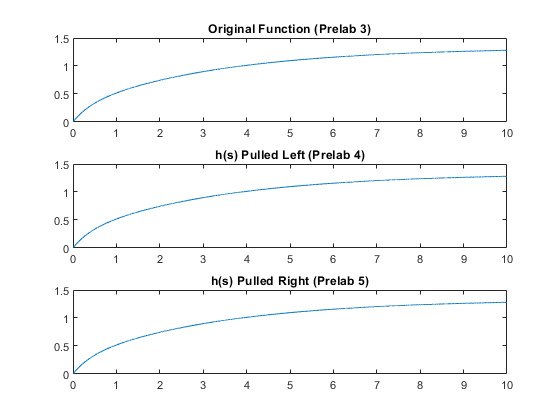

plot(simOut.question.Time, simOut.question.Data)
title("h(s) Pulled Right (Prelab 5)")

## Postlab

### Problem 1

*Using your lab data, verify the equivalent transfer function of blocks in cascade.*

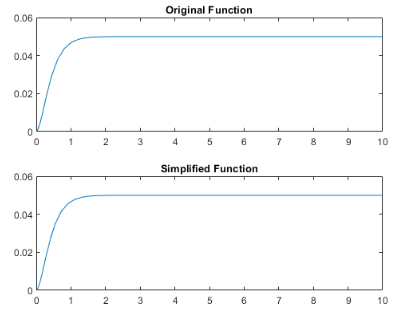

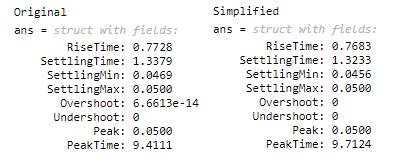

As it can be seen, the step response and transient metrics are near identical with there only being slight differences of at most 0.1 between the setting time and rise time due to how matlab approximates these values. This verifies that these two transfer functions are equivalent. 

### Problem 2

*Using your lab data, verify the equivalent transfer function of block in parallel.*

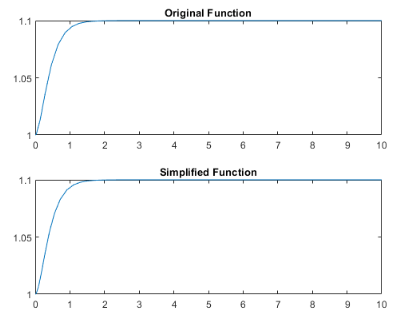

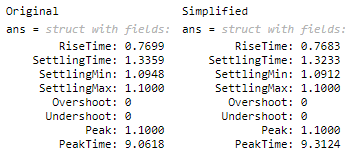

Again, the step response and trainsient metrics are nearly identical with the biggest differences being peak time by 0.1 between the settling time and rise time most likely due to matlab's approximations in calculating these values. The simularity of the simplified and original graphs, within a margin of error, shows that these systems are identical.

### Problem 3

*Using your lab data, verify the equivalent transfer function of negative feedback systems.*

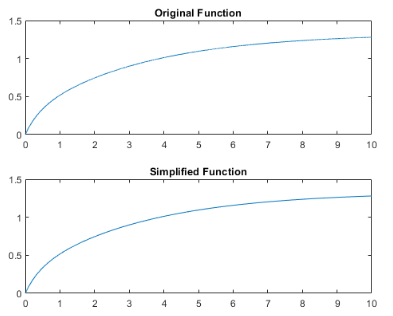

### 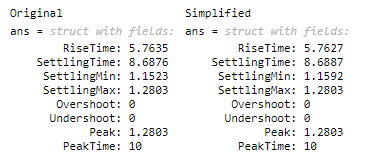

The step response and trainsient metrics once again match with there only being slight differences of 0.001 at maximum in the in settling time and rise time. Since the step response of the original system and the simplified system show the same charecteristics and the trainsient metrics are near identical, the simplification of the system is equivalent. 

### Problem 4

*Using your lab data, verify the moving of blocks past summing junctions and pickoff points.*

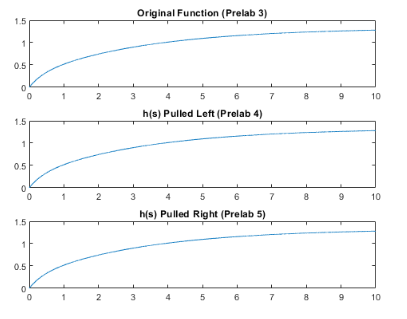

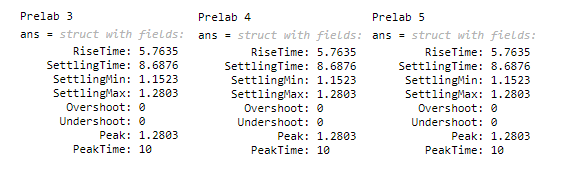

As it can be seen above, when h(s) is pulled before the summing junction or after the pickoff point and the feedback loop is algebraically adjusted accordinally as seen in the lab, the system remains equivelent. The step responses of the three system forms are graphically identical and the trainsient metrics of each are exactly the same. 

### Problem 5

*Discuss your results. Were the equivalencies verified?*

In all expansions or simplifications of the systems given above, the step response of that system remained the same. Therefore, all equivalencies were verified. Since these systems are LTI, all other inputs will also have matching outputs no matter if they are in their expanded or simplified forms. It was seen above that occasionally the trainsient metrics would differ by as much as 0.1 between the simplied version and the unsimplified version but this is most likely due to the approximations matlab makes when calculating these values. 

It can be concluded from this experient that pieces of a system can be combined together or extracted as long as algebraic compensations are made to keep the entire system equivelant. This can be useful for when simplifing a complex system down to a transfer function, or expanding a system into a desired form. 